# DC_LAB3_AngularVelocity

addpath("plot\");
addpath("Linearization\");
addpath("Modeling\");

## 1. Figure out Steady State 

### 1) Rising time 2.5[sec]

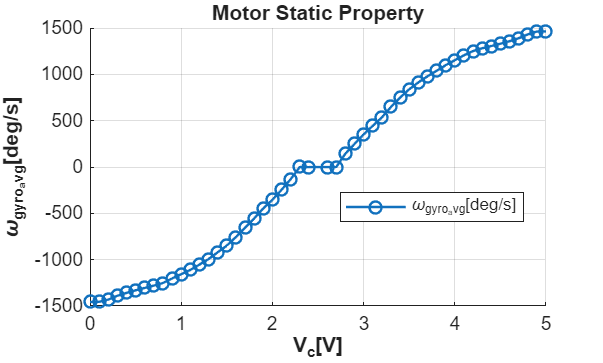

plot_sweep('../data/Static/Static_0.1.out');

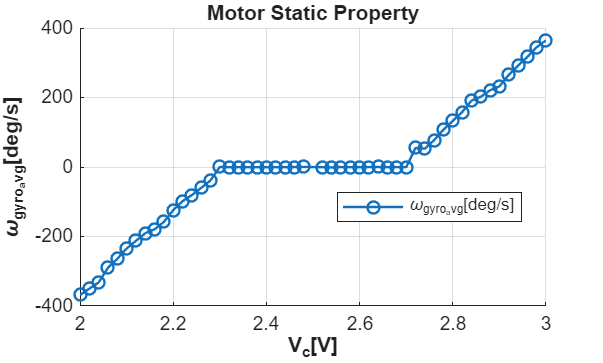

plot_sweep('../data/Static/Static.out');

Get_fitting_Quadratic('../data/Static/Static_0.1.out');

Positive region: W = -274.4147*V^2 + 2725.1332*V + -5352.2284
Negative region: W = 296.2148*V^2 + -78.8436*V + -1383.6486


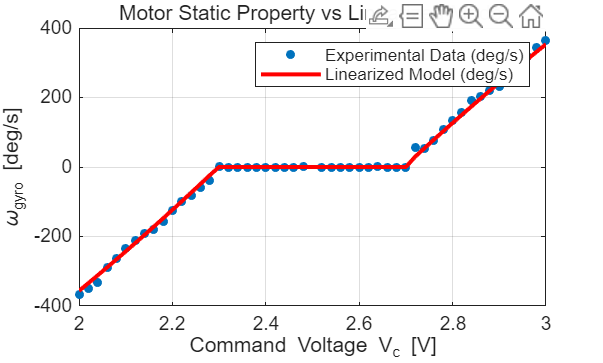

Linear_mapping('../data/Static/Static.out'); 

## 2. Obtain Static Motor Property

### 1) Dead-zone at 2.3[V] -> 2.7[V] voltage

### 2) Saturation of Wgyro to 25 [rad/ses] (219 rpm)  (3.66 Hz)

### 3) Linear region positive from 2.7[V] to 3.5[V], negative from 2.3[V] to 1.5[V]

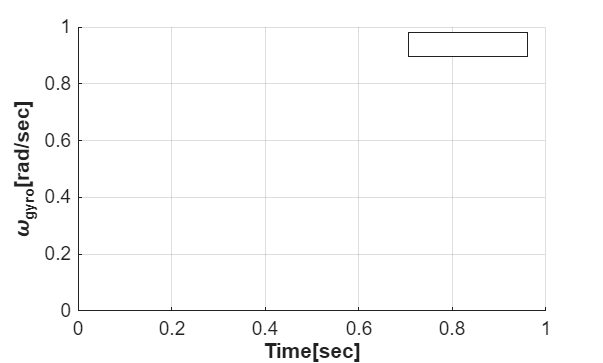

plot_Wgyro('Slewrate');


find_coff(0.05, 0.2302, 1.842, 2.72, 2.85, 4.80);

find_coff을(를) 현재 폴더 또는 MATLAB 경로에서 찾을 수 없지만 다음 위치에 있습니다.
 C:\semester 5\DSCP\Gimbal\DC_PRO (2)\MATLAB
    C:\semester 5\DSCP\Gimbal\DC_PRO\MATLAB

MATLAB 현재 폴더를 변경하십시오 또는 해당 폴더를 MATLAB 경로에 추가하십시오.

find_coff(-0.05,-0.2436,-1.7824,2.28,2.15,0.3);


## 3. Validation - triangle

Vali_plot('tri');
Vali_plot('sin');


## 4. Bode 

% plot_BodeMag_dB('BodeMag');

[freqs, gains, phases]= generate_bode_plot('..\data\BodeMag');

disp(freqs);
disp(gains);
disp(phases);

plot_BodeMag_dB()